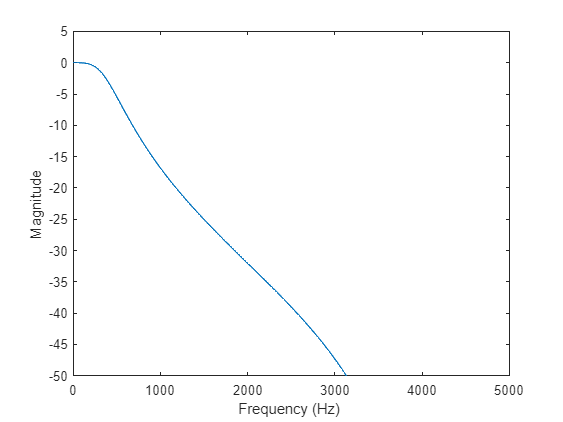

fs=8000; % sampling rate for discrete signal
[b, a]=butter(2,400/(fs/2));
[h,f]=freqz(b,a,512,fs); % Digital filter frequency response
figure(1)
plot(f,20*log10(abs(h))); % in dB scale
axis([0 5000 -50 5]);
xlabel('Frequency (Hz) ');
ylabel('Magnitude');

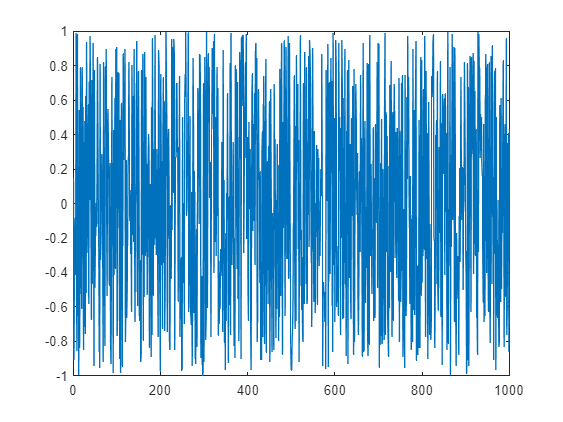

N=1000; 
noise = 1-2*rand(1,N);
figure(2)
plot(1:N, noise)


% [Pxx,w] =psd(sig,512,fs); 


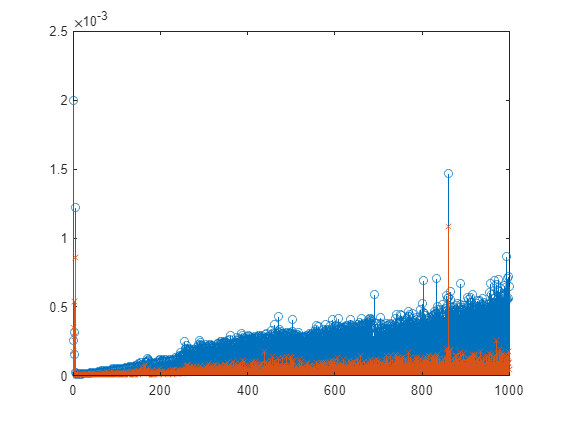

clear; clc; close;
NN = 1000;
ctime = zeros(1,NN);
ftime = zeros(1,NN);
for N=1:NN
    tic;
    n = 0:(N-1);
    x = 0.9 .^ n;
    h = 0.5 .^ n;
    x_h = conv([x x], h);
    y = x_h((N+1):2*N);
    ctime(N)=toc;

    tic
    fft_x = fft(x);
    fft_h = fft(h);
    fft_y = fft_x .* fft_h;
    y_ifft = ifft(fft_y);
    ftime(N)=toc;
end

stem(1:NN, ctime);
hold on;
stem(1:NN, ftime, 'x');